# One-layer perceptron

Erik Norlin

trainingSet = readmatrix("training_set.csv");
validationSet = readmatrix("validation_set.csv");

% Normalizing the training and validation data set
nTrainingSetPatterns = height(trainingSet);
meanTrainingSet1 = 0;
meanTrainingSet2 = 0;
for i = 1:nTrainingSetPatterns
    meanTrainingSet1 = meanTrainingSet1 + trainingSet(i,1);
    meanTrainingSet2 = meanTrainingSet2 + trainingSet(i,2);
end
meanTrainingSet1 = meanTrainingSet1 / nTrainingSetPatterns;
meanTrainingSet2 = meanTrainingSet2 / nTrainingSetPatterns;

varianceTrainingSet1 = 0;
varianceTrainingSet2 = 0;
for i = 1:nTrainingSetPatterns
    varianceTrainingSet1 = varianceTrainingSet1 + (trainingSet(i,1) - meanTrainingSet1)^2;
    varianceTrainingSet2 = varianceTrainingSet2 + (trainingSet(i,2) - meanTrainingSet2)^2;
end
standardDeviationTrainingSet1 = sqrt(varianceTrainingSet1 / nTrainingSetPatterns);
standardDeviationTrainingSet2 = sqrt(varianceTrainingSet2 / nTrainingSetPatterns);

normTrainingSet = zeros(nTrainingSetPatterns,3);
for i = 1:nTrainingSetPatterns
    normTrainingSet(i,1) = (trainingSet(i,1) - meanTrainingSet1) / standardDeviationTrainingSet1;
    normTrainingSet(i,2) = (trainingSet(i,2) - meanTrainingSet2) / standardDeviationTrainingSet2;
    normTrainingSet(i,3) = trainingSet(i,3);
end

nValidationSetPatterns = height(validationSet);
normValidationSet = zeros(nValidationSetPatterns,3);
for i = 1:nValidationSetPatterns
    normValidationSet(i,1) = (validationSet(i,1) - meanTrainingSet1) / standardDeviationTrainingSet1;
    normValidationSet(i,2) = (validationSet(i,2) - meanTrainingSet2) / standardDeviationTrainingSet2;
    normValidationSet(i,3) = validationSet(i,3);
end

nHiddenNeurons = 12;
nEpochs = 150;
eta = 0.011;
classError = zeros(nEpochs,1);

nInputNeurons = 2;
nOutputNeurons = 1;

v_j = zeros(nHiddenNeurons,1);
w_ij = randn(nOutputNeurons,nHiddenNeurons);
w_jk = randn(nHiddenNeurons,nInputNeurons);
theta_j = zeros(nHiddenNeurons,1);
theta_i = 0;

b_j = zeros(nHiddenNeurons,1);
b_i = zeros(nOutputNeurons,1);

deltaError1 = zeros(nOutputNeurons,1);
deltaError2 = zeros(nHiddenNeurons,1);

deltaWeight_ij = zeros(nOutputNeurons,nHiddenNeurons);
deltaWeight_jk = zeros(nHiddenNeurons,nInputNeurons);
deltaTheta_j = zeros(nHiddenNeurons,1);
deltaTheta_i = zeros(nOutputNeurons,1);

energyTrainingSet = zeros(nEpochs,1);
energyValidationSet = zeros(nEpochs,1);
minClassError = 1;

% Training the network
for iEpoch  = 1:nEpochs 
    
    nPatterns = nTrainingSetPatterns;
    for muPattern = 1:nPatterns
        
        randomPattern = randi(nPatterns);
        inputPattern = normTrainingSet(randomPattern,:);
        x_k = inputPattern(1:2)';
        target = inputPattern(3);
        
        % Forward propagating
        for jNeuron = 1:nHiddenNeurons
            b_j(jNeuron) = w_jk(jNeuron,:)*x_k - theta_j(jNeuron);
            v_j(jNeuron) = tanh(b_j(jNeuron));
        end
        
        b_i = w_ij*v_j - theta_i;
        output = tanh(b_i);
        
        % Calculating the energy of the output
        energyTrainingSet(iEpoch) = energyTrainingSet(iEpoch) + ((target - output)^2)/2;
        
        % Computing errors and backpropagating
        deltaError1 = (target - output)*((sech(b_i))^2);
        for jNeuron = 1:nHiddenNeurons
            deltaError2(jNeuron) = deltaError1*(w_ij(jNeuron)*((sech(b_j(jNeuron)))^2));
        end
        
        for jNeuron = 1:nHiddenNeurons
            deltaWeight_ij(jNeuron) = eta*deltaError1*v_j(jNeuron);
        end
        for kInput = 1:nInputNeurons
            for jNeuron = 1:nHiddenNeurons
               deltaWeight_jk(jNeuron,kInput) = eta*deltaError2(jNeuron)*x_k(kInput); 
            end
        end

        deltaTheta_i = -eta*deltaError1;
        for jNeuron = 1:nHiddenNeurons
            deltaTheta_j(jNeuron) = -eta*deltaError2(jNeuron); 
        end
        
        % Updating weights and thresholds
        w_ij = w_ij + deltaWeight_ij;
        theta_i = theta_i + deltaTheta_i;
        
        w_jk = w_jk + deltaWeight_jk;
        theta_j = theta_j + deltaTheta_j;
    end
    
    % Validating the trained network with the validation data set
    pVal = nValidationSetPatterns;
    for muPattern = 1:pVal
        
        % Forward propagating a random pattern from the valiadation set
        randomPattern = randi(muPattern);
        inputPattern = normValidationSet(randomPattern,:);
        x_k = inputPattern(1:2)';
        target = inputPattern(3);
        
        for jNeuron = 1:nHiddenNeurons
            b_j(jNeuron) = w_jk(jNeuron,:)*x_k - theta_j(jNeuron);
            v_j(jNeuron) = tanh(b_j(jNeuron));
        end
        
        b_i = w_ij*v_j - theta_i;
        output = tanh(b_i);
        if output == 0
            output = 1;
        end
        
        % Calculating energy and classification error
        classError(iEpoch)= classError(iEpoch) + abs(sign(output) - target);
        energyValidationSet(iEpoch) = energyValidationSet(iEpoch) + ((target - output)^2)/2;
    end
    
    classError(iEpoch) = classError(iEpoch)/(2*pVal);
    if classError(iEpoch) < minClassError
        minClassError = classError(iEpoch);
    end
end

writematrix(w_jk,"w1.csv");
writematrix(w_ij',"w2.csv");
writematrix(theta_j,"t1.csv");
writematrix(theta_i,"t2.csv");

% Averaging the energy from respective data set to be able to compare them
energyTrainingSet = energyTrainingSet ./ height(normTrainingSet);
energyValidationSet = energyValidationSet ./ height(normValidationSet);

figure
hold on
plot(1:nEpochs,energyTrainingSet,"-");
plot(1:nEpochs,energyValidationSet,"-");
xlabel("Epochs")
ylabel("Average Energy, H")
legend({'trainingset','validationset'});
minClassErrorProcent = minClassError*100;
fprintf("Number of hidden neurons: %d\nClassification error: %.1f%%", nHiddenNeurons,minClassErrorProcent);

Number of hidden neurons: 12
Classification error: 10.7%

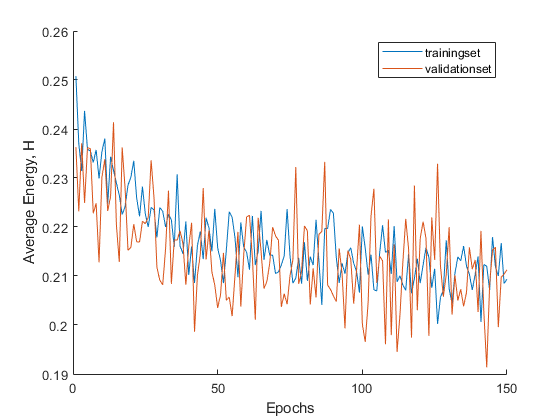

hold off

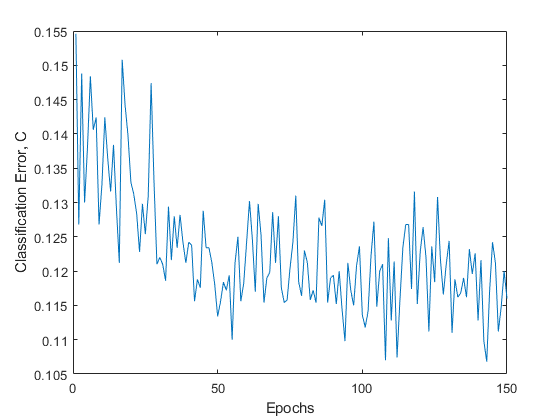


figure 
plot(1:nEpochs,classError,"-");
xlabel("Epochs")
ylabel("Classification Error, C")